## Current TO-Dos

- i added a buffer to the transmit signal to speed up the simulation time, however its currently sampling the whole ADC sampling period. I need it to sample just the "sampling" period. Need to update the script and the simulink model to reflect this

## Initialize the simulator

clear;
simulator = Simulator_revA();
%setup the victim's chirp parameters

simulator.load_B210_victim_params;
simulator.load_B210_attacker_params;

%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default target, attacker, and victim positions and velocities
simulator.load_target_realistic;
simulator.load_realistic_attacker_and_victim_position_and_velocity();

%print out key parameters
simulator.Victim.print_chirp_parameters;

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.20 MHz/us
	 Idle Time: 			 1.95 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.49 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 1.54 MSps
	 Ramp End Time: 		 48.05 us
	 Chirp Tx Bandwidth: 		 57.66 MHz
	 Chirp Sampling Bandwidth: 	 49.87 MHz
	 ADC Sampling Period: 		 41.56 us
	 Chirp Cycle Time: 		 50.00 us
	 Chirp Wavelength: 		 3.89 mm



simulator.Victim.print_frame_parameters;

Frame Parameters
	 Number of Chirps 		 32
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 1.60 ms


simulator.Victim.print_performance_specs;

Performance Specifications
	 Max Range 			 192.37 m
	 Range Resolution 		 3.01 m
	 Max Velocity 			 19.47 m/s
	 Velocity Resolution 		 1.22 m/s


simulator.Victim.print_FMCW_specs;

FMCW Specifications
	 FMCW sampling rate 		 58.52 MHz
	 Downsampling factor 		 38
	 Sweep time 			 48.05 us


simulator.Attacker.Subsystem_tracking.print_chirp_parameters;

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.20 MHz/us
	 Idle Time: 			 1.95 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.49 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 1.54 MSps
	 Ramp End Time: 		 48.05 us
	 Chirp Tx Bandwidth: 		 57.66 MHz
	 Chirp Sampling Bandwidth: 	 49.87 MHz
	 ADC Sampling Period: 		 41.56 us
	 Chirp Cycle Time: 		 50.00 us
	 Chirp Wavelength: 		 3.89 mm


simulator.Attacker.Subsystem_tracking.print_frame_parameters;

Frame Parameters
	 Number of Chirps 		 32
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 1.60 ms


simulator.Attacker.Subsystem_tracking.print_performance_specs;

Performance Specifications
	 Max Range 			 192.37 m
	 Range Resolution 		 3.01 m
	 Max Velocity 			 19.47 m/s
	 Velocity Resolution 		 1.22 m/s


simulator.Attacker.Subsystem_tracking.print_FMCW_specs;

FMCW Specifications
	 FMCW sampling rate 		 58.52 MHz
	 Downsampling factor 		 38
	 Sweep time 			 48.05 us


Proof of concept for the attacker

%TEMPORARY FUNCTION - import the victim chirp parameters for the attacker
%module
simulator.Attacker.import_parameters_from_victim(simulator.Victim);

%specify the attack to be added at 30m with a velocity of 15 m
simulator.Attacker.set_desired_attack_parameters(80,15)


%compute the other calculated values for the attacker
simulator.Attacker.Subsystem_attacking.compute_calculated_values;

Writing code to simulate the signal propogation through the signal processing chain

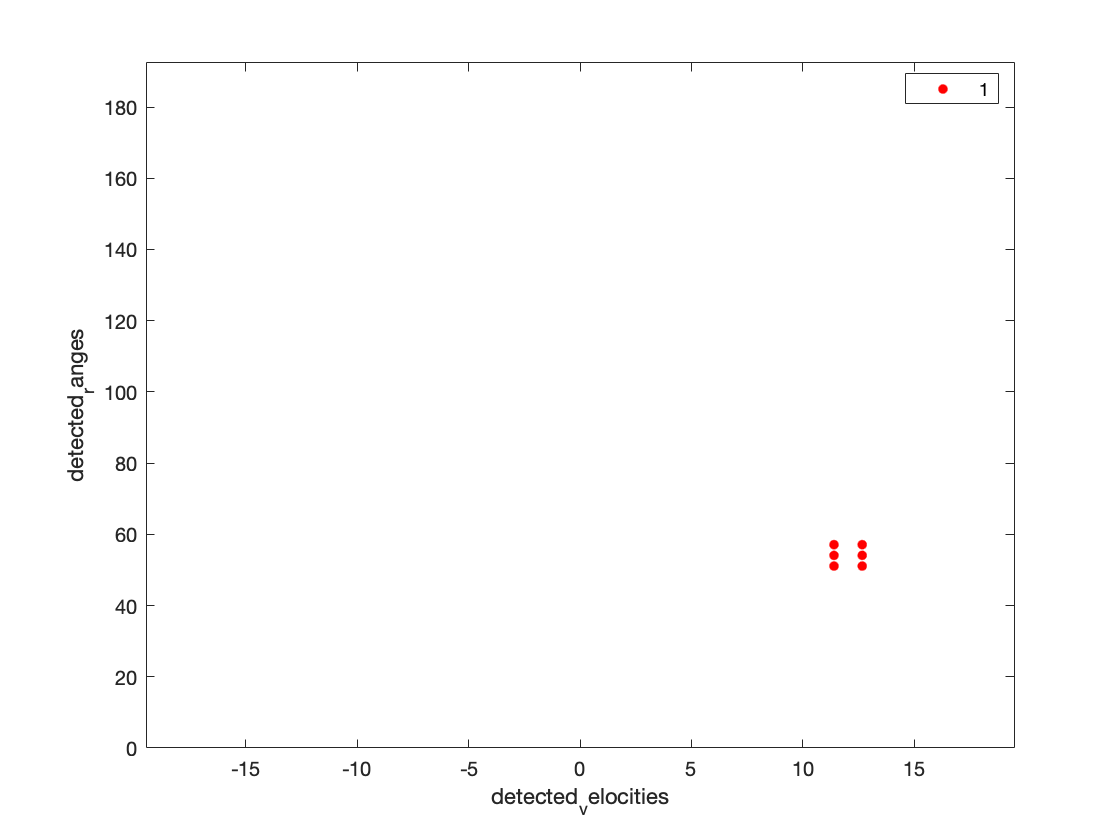

frames_to_compute = 1;
chirps_to_compute = simulator.Victim.NumChirps;

%configure it so that I can generate a movie
F_rngdop(frames_to_compute) = struct('cdata',[],'colormap',[]);
F_clusters(frames_to_compute) = struct('cdata',[],'colormap',[]);

for frame = int32(1:frames_to_compute)
% frame = 1;
    
    
    %compute the location of the victim and the target
    [victim_pos, victim_vel,attacker_pos, attacker_vel, tgt_pos,tgt_vel] = simulator.FMCW_determine_positions_and_velocities(double(frame),1);    
    
    simulator.Attacker.Subsystem_attacking.update_attacker_chirps(frame,attacker_pos,victim_pos);

    radar_cube = zeros(simulator.Victim.ADC_Samples,simulator.Victim.NumChirps);
    
    for chirp = int32(1:chirps_to_compute)
    
        %generate the chirp
        FMCW_chirp = simulator.Victim.chirp;
        
        %send through the transmitter
        Tx_sig = simulator.Victim.transmitter(FMCW_chirp);
        
        %compute the location of all the victim, attacker, and target at
        %the end of the frame (this is how distance is managed in the
        %simulink model so i'm replicating it here.) 
        [victim_pos, victim_vel,attacker_pos, attacker_vel, tgt_pos,tgt_vel] = ...
            simulator.FMCW_determine_positions_and_velocities(double(frame),double(chirp));
        
        %victim Radar processing

        
        free_space_sig = simulator.channel_target(Tx_sig,victim_pos,tgt_pos,victim_vel,tgt_vel);
        
        %reflect off of the target
        reflected_sig = simulator.SimulatedTarget.radar_target(free_space_sig);
        
        %add in the attacker
        free_space_sig_attacker = simulator.channel_attacker(...
            simulator.Attacker.Subsystem_attacking.get_transmitted_attacker_chirp(chirp),...
            attacker_pos,victim_pos,attacker_vel,victim_vel);

        %simulate the attack occurring after a specified number of frames
        combined_sig = reflected_sig;

%         if frame < 30
%             combined_sig = free_space_sig;
%         else
%             combined_sig = free_space_sig + free_space_sig_attacker;
%         end        
        
        %process the signal through the receiver
        Rx_sig = simulator.Victim.receiver(combined_sig);
        
        %dechirp and downsample the signal
        sampled_IF_sig = simulator.Victim.FMCW_simulate_dechirp_and_downsample(Tx_sig,Rx_sig);
        
        %assemble the radar cube
        radar_cube(:,chirp) = sampled_IF_sig;
    end
    
    %range-doppler response
    [resp, rnggrid,dopgrid] = simulator.Victim.RangeDopplerResponse(radar_cube);

    %plot the doppler response and sae it for a movie
    plotResponse(simulator.Victim.RangeDopplerResponse,radar_cube);
    drawnow
    F_rngdop(frame) = getframe(gcf);
    
    %CA CFAR 2-D
    detections = simulator.Victim.CFARDetector2D(abs(resp).^2,simulator.Victim.CUT_indicies);
    detected_velocities = dopgrid(detections(2,:));
    detected_ranges = rnggrid(detections(1,:));
    
    %DBSCAN Clustering
    idx = dbscan(detections.',simulator.Victim.Epsilon,simulator.Victim.minpts);

    %plot the clusters
    gscatter(detected_velocities,detected_ranges,idx);
    axis([-1 * simulator.Victim.V_Max_m_per_s, simulator.Victim.V_Max_m_per_s, 0,simulator.Victim.Range_Max_m]);
    drawnow
    F_clusters(frame) = getframe(gcf);
end

%play the movie for the range doppler
fig = figure;
movie(fig,F_rngdop,1,10)

%play the movie for the clusters
fig = figure;
movie(fig,F_clusters,1,10)

## Simulink Model

### Initialize Simulink Model

%initialize other variables needed in the simulation

%variables needed specifically for the simulink model

%for the radar modules
num_samples_prior_to_sample_period = ...
    int32((simulator.Victim.ADC_ValidStartTime_us +...
    simulator.Victim.IdleTime_us * 1e-6) *...
    simulator.Victim.ADC_SampleRate_MSps);
num_samples_in_sampling_period = simulator.Victim.ADC_Samples;

victim_num_adc_samples = simulator.Victim.ADC_Samples;


%open the simulink model

open_system('FMCWSim');
stop_time = (frames_to_compute - 1) * simulator.Victim.FramePeriodicity_ms * 1e-3...
    + (chirps_to_compute * simulator.Victim.ChirpCycleTime_us * 1e-6);
% stop_time = (frames_to_compute - 1) * simulator.Victim.FramePeriodicity_ms * 1e-3...
%     + (simulator.Victim.NumChirps * simulator.Victim.ChirpCycleTime_us * 1e-6);
set_param('FMCWSim','StopTime','stop_time');
warning_to_suppress_id = 'Coder:MATLAB:illConditionedMatrix';
warning('off',warning_to_suppress_id);
out = sim('FMCWSim','SimulationMode','accelerator','SaveOutput','on');

### Tx Sig

%check a few chirps later to ensure that no timing errors or drift
Tx_sig_simulink = out.Tx_sig(:,:,2);
compare = all(Tx_sig == Tx_sig_simulink,'all');

if compare
    fprintf("Tx Signal: \t\t Matches")
else
    fprintf("Tx Signal: \t\t Does Not Match")
end

Tx Signal: 		 Matches

### Position and Velocity

victim_pos_simulink = out.victim_pos(:,:,2);
victim_vel_simulink = out.victim_vel(:,:,2);
tgt_pos_simulink = out.tgt_pos(:,:,2);
tgt_vel_simulink = out.tgt_vel(:,:,2);

compare = all(abs(victim_pos - victim_pos_simulink) < 1e-10,'all');
if compare
    fprintf("Victim Position: \t\t Matches")
else
    fprintf("Victim Position: \t\t Does Not Match")
end

Victim Position: 		 Matches


compare = all(victim_vel == victim_vel_simulink,'all');
if compare
    fprintf("Victim Velocity: \t\t Matches")
else
    fprintf("Victim Velocity: \t\t Does Not Match")
end

Victim Velocity: 		 Matches


compare = all(abs(tgt_pos - tgt_pos_simulink) < 1e-10,'all');
if compare
    fprintf("Target Position: \t\t Matches")
else
    fprintf("Target Position: \t\t Does Not Match")
end

Target Position: 		 Matches


compare = all(tgt_vel == tgt_vel_simulink,'all');
if compare
    fprintf("Target Velocity: \t\t Matches")
else
    fprintf("Target Velocity: \t\t Does Not Match")
end

Target Velocity: 		 Matches

### Free Space Signal

%check a few chirps later to ensure that no timing errors or drift
free_space_sig_simulink = out.free_space_sig(:,:,2);
compare = all(abs(free_space_sig - free_space_sig_simulink) < 1e-10,'all');

if compare
    fprintf("Free Space Signal: \t\t Matches")
else
    fprintf("Free Space Signal: \t\t Does Not Match")
end

Free Space Signal: 		 Matches

### Reflected Signal

%check a few chirps later to ensure that no timing errors or drift
reflected_sig_simulink = out.reflected_sig(:,:,2);
compare = all(abs(reflected_sig - reflected_sig_simulink) < 1e-10,'all');

if compare
    fprintf("Free Space Signal: \t\t Matches")
else
    fprintf("Free Space Signal: \t\t Does Not Match")
end

Free Space Signal: 		 Matches

### Rx Sig

Note: The Receiver Preamp inserts random noise into the signal. As such, the results will not match up perfectly here or moving forward

%check a few chirps later to ensure that no timing errors or drift
Rx_sig_simulink = out.Rx_sig(:,:,2);
compare = all(abs(Rx_sig - Rx_sig_simulink) < 1e-5,'all');

if compare
    fprintf("Rx Signal: \t\t Matches")
else
    fprintf("Rx Signal: \t\t Does Not Match")
end

Rx Signal: 		 Matches

### Sampled IF Signal

%check a few chirps later to ensure that no timing errors or drift
sampled_IF_sig_simulink = out.sampled_IF_sig(:,:,2);
compare = all(abs(sampled_IF_sig - sampled_IF_sig_simulink) < 1e-5,'all');

if compare
    fprintf("Sampled IF Signal: \t\t Matches")
else
    fprintf("Sampled IF Signal: \t\t Does Not Match")
end